# 浙江大学实验报告

课程名称：信号与系统

实验名称：

实验日期：

姓名：毛永奇

学号：3220103385

## 实验目的

- 综合运用信号和系统的时、频域分析方法，对音频信号进行分析和处理

## 实验原理

        我们听到的声音可以看成是连续时间信号，其类型可以大体划分为语音、乐 音、噪声等几种类型；

        而数字设备中保存的声音可看成是以一定的采样率对连续时间信号采样得到的离散时间样值序列，如普通 CD 的采样频率是 44.1 kHz。

        因此我们可以利用学过的信号与系统的知识，通过编程对声音进行简单的分析和处理。

        本次实验中，我选取了采样频率32000Hz的音频作为分析对象。

        通过audioread获取音频信息，通过sound函数播放。通过imread和imshow读取和展示图像。

        实验中多次使用滤波方法，低通滤波的原理就是对信号的傅里叶变换进行处理，过滤掉低频信号，高通滤波同理。由此可以对声音和画面进行特征提取。

## 实验内容

一、

% 读入声音文件，请保证目标文件和mlx文件在同一目录
[y, Fs] = audioread('1.wav');
% (a) 采样率、时域波形和频谱特征
fprintf('采样率：%d Hz\n', Fs);

采样率：32000 Hz


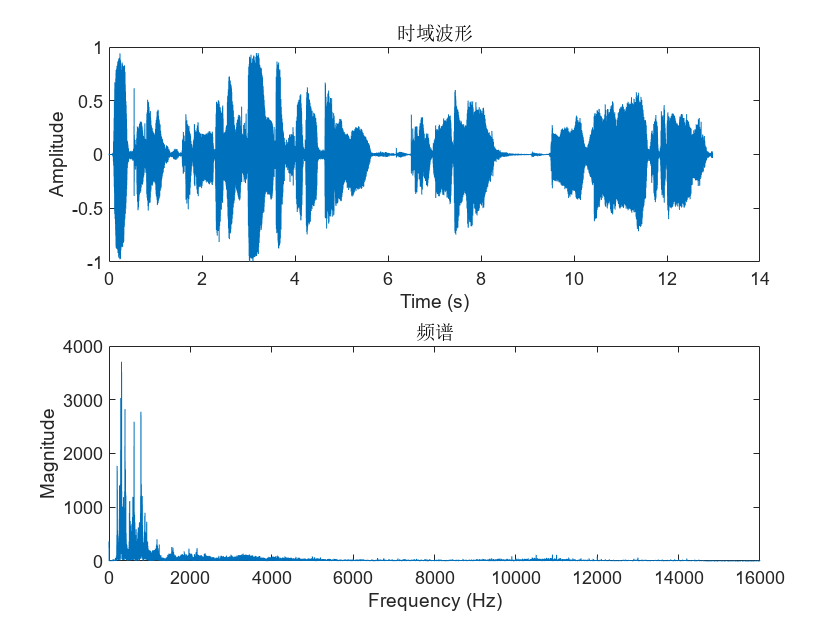

time = (0:length(y)-1) / Fs;
subplot(2,1,1);
plot(time, y);
title('时域波形');
xlabel('Time (s)');
ylabel('Amplitude');
%获得频谱
Y = fft(y);
N = length(Y); 
f = linspace(0, Fs/2, N/2); 
half_spectrum = abs(Y(1:N/2));
subplot(2,1,2);
plot(f, half_spectrum);
title('频谱');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

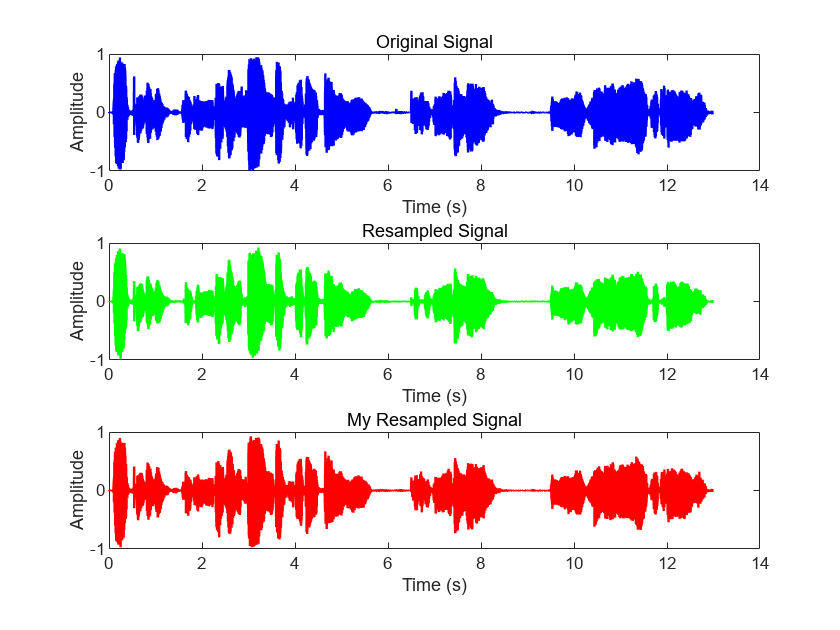


% (b) 重采样
% 1）使用matlab的resample函数，避免失真
Fs_resampled = 4000; % 设置重采样后的采样率为4 kHz
y_resampled = resample(y, Fs_resampled, Fs);

% 2）手动重采样
% 原始采样率
Fs_old = Fs;

% 新的采样率
Fs_new = 4000;

% 时间向量
t_old = (0:length(y)-1) / Fs_old;
t_new = (0:round((length(y)-1) * Fs_new / Fs_old)) / Fs_new;

% 线性插值重采样
my_y_resampled = interp1(t_old, y, t_new, 'linear');

% 3)绘制原始信号和重采样后的信号波形
figure;
subplot(3,1,1);
plot(t_old, y, 'b-', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');

subplot(3,1,2);
t__new = t_new(1:end-1);
plot(t__new, y_resampled, 'g-', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Resampled Signal');

subplot(3,1,3);
plot(t_new, my_y_resampled, 'r-', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('My Resampled Signal');

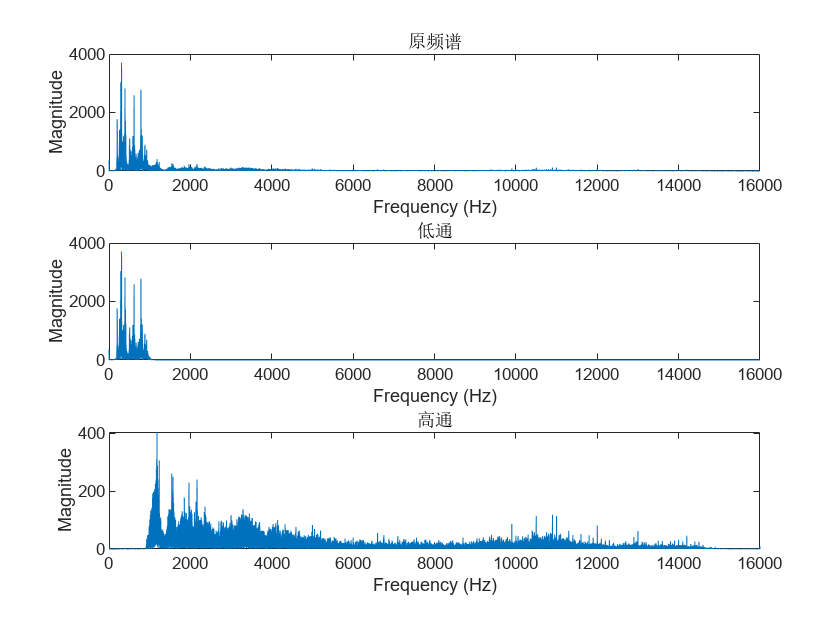

% (c) 滤波处理
% 1）低通滤波
fc = 1000; % 截止频率1k Hz
order = 500; % 阶数
b = fir1(order, fc/(Fs/2)); % 设计FIR低通滤波器
y_lowpass = filter(b, 1, y); % 对信号进行滤波处理

%2）高通滤波
fcc = 1000; % 高通过滤截止频率为1k Hz
high_order = 500; % 阶数
c = fir1(high_order, fcc/(Fs/2), 'high');
y_highpass = filter(c, 1, y);

%3）分析滤波效果
figure;

half_spectrum = abs(Y(1:N/2));
subplot(3,1,1);
plot(f, half_spectrum);
title('原频谱');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

Y_low_filtered = fft(y_lowpass);
half_spectrum = abs(Y_low_filtered(1:N/2));
subplot(3,1,2);
plot(f, half_spectrum);
title('低通');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

Y_high_filtered = fft(y_highpass);
half_spectrum = abs(Y_high_filtered(1:N/2));
subplot(3,1,3);
plot(f, half_spectrum);
title('高通');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

%1)原声
sound(y, Fs); % 播放原始声音
pause(length(y)/Fs); % 等待原始声音播放完
%2)matlab自带重采样
sound(y_resampled, Fs_resampled); % 播放重采样后的声音
pause(length(y_resampled)/Fs_resampled); % 等待重采样声音播放完
%3)手写重采样
sound(my_y_resampled, Fs_resampled); % 播放重采样后的声音
pause(length(y_resampled)/Fs_resampled); % 等待重采样声音播放完
%4)滤波
sound(y_lowpass, Fs); % 播放低通滤波后的声音
pause(length(y_lowpass)/Fs);
sound(y_highpass, Fs);% 播放高通滤波后的声音

四、

% 读取原始彩色图像
original_image = imread('2.png');


% 低通滤波
h = fspecial('average', [100 100]); % 3x3平均滤波器
lowpass_image = imfilter(original_image, h);

% 高通滤波
highpass_image = original_image - lowpass_image;

% 将高通滤波后的图像限制在 0 到 255 的范围内
highpass_image = max(0, min(highpass_image, 255));

% 细节增强
enhanced_image = original_image + 1.5 * highpass_image;

% 将细节增强后的图像限制在 0 到 255 的范围内
enhanced_image = max(0, min(enhanced_image, 255));

% 显示原始图像、低通滤波后的图像、高通滤波后的图像和细节增强图像
figure;
subplot(1,4,1);
imshow(original_image);
title('Original Image');

subplot(1,4,2);
imshow(lowpass_image);
title('Lowpass Filtered Image');

subplot(1,4,3);
imshow(highpass_image);
title('Highpass Filtered Image');
subplot(1,4,4);
imshow(enhanced_image);
title('Enhanced Image');

## 实验总结

1）实验一中，我使用了两种方法进行重采样，一个是matlab自带函数，另一个是手写的插值法，从声音中可以听出手写的插值法失真显然更明显，验证了指导书中的说法，matlab使用了低通反混叠；

对于低通滤波和高通滤波，我都进行了尝试，一开始发现低通滤波后还有很明显的高频成分，加大阶数也没用，后来发现应该是频谱图中低频和高频对称的现象是由于实信号的频谱是对称的，所以截取半段即可。

对于阶数的选择，一开始使用50阶，但看频谱发现不能较好滤波，所以换成了500阶，效果显著。

使用1kHz作为低频和高频的分界，对比两组声音，可以发现歌曲声音基本分布在500~1000Hz，低通的音质保持更好，而高通就很明显失真。

2）实验四中，我学习应用了低通滤波和高通滤波对图像尝试的效果，可以看到低通滤波模糊了图像，高通滤波提取轮廓，而把原图像和高通滤波叠加可以得到细节增强图像。